clc; clear;

Gait parameter 설정

t = 0;
b = 0;
b2 = 0;

a = deg2rad(45);
a2 = deg2rad(45);

% a = 1;
% a2 = 1;

e_d1 = deg2rad(30);
e_l1 = deg2rad(30);

e_d2 = 6;
e_l2 = 3;

delta = deg2rad(90);

각도 데이터 생성 및 플롯

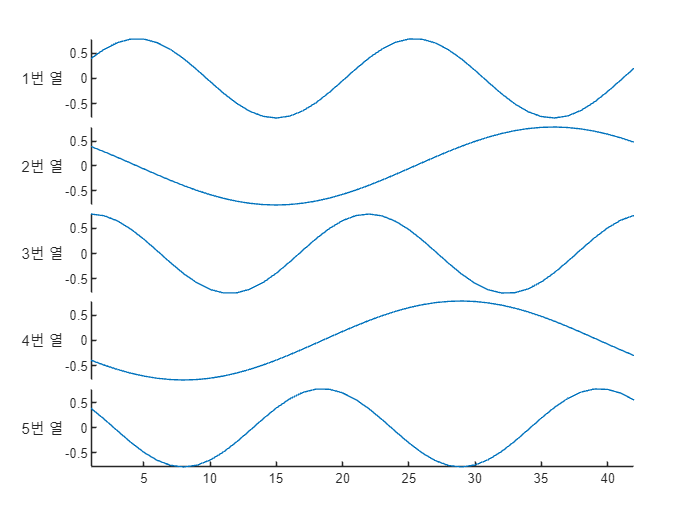

% t = transpose(0:0.1:lcm(lcm(1/e_d2,1/e_l2),2) * pi);
t = transpose(0:0.05: (2*pi/gcd(e_d2 * 10,e_l2 * 10) * 10));

joint_data = serpenoid(t, b, b2, a, a2, e_d1, e_d2, e_l1, e_l2, delta);
joint_data = joint_data(:,1:14);
d_joint_data = diff(joint_data) * (1/0.01);
dd_joint_data = diff(d_joint_data) * (1/0.01);

logic_joint = joint_data;
logic_joint(:,1) = ((min(logic_joint(:,1)) * 0.75) > logic_joint(:,1)) + ((max(logic_joint(:,1)) * 0.75) < logic_joint(:,1));
logic_joint(:,2) = ((min(logic_joint(:,2)) * 0.75) > logic_joint(:,2)) + ((max(logic_joint(:,2)) * 0.75) < logic_joint(:,2));
logic_joint(:,3) = ((min(logic_joint(:,3)) * 0.75) > logic_joint(:,3)) + ((max(logic_joint(:,3)) * 0.75) < logic_joint(:,3));
logic_joint(:,4) = ((min(logic_joint(:,4)) * 0.75) > logic_joint(:,4)) + ((max(logic_joint(:,4)) * 0.75) < logic_joint(:,4));
logic_joint(:,5) = ((min(logic_joint(:,5)) * 0.75) > logic_joint(:,5)) + ((max(logic_joint(:,5)) * 0.75) < logic_joint(:,5));
logic_joint(:,6) = ((min(logic_joint(:,6)) * 0.75) > logic_joint(:,6)) + ((max(logic_joint(:,6)) * 0.75) < logic_joint(:,6));
logic_joint(:,7) = ((min(logic_joint(:,7)) * 0.75) > logic_joint(:,7)) + ((max(logic_joint(:,7)) * 0.75) < logic_joint(:,7));
logic_joint(:,8) = ((min(logic_joint(:,8)) * 0.75) > logic_joint(:,8)) + ((max(logic_joint(:,8)) * 0.75) < logic_joint(:,8));
logic_joint(:,9) = ((min(logic_joint(:,9)) * 0.75) > logic_joint(:,9)) + ((max(logic_joint(:,9)) * 0.75) < logic_joint(:,9));
logic_joint(:,10) = ((min(logic_joint(:,10)) * 0.75) > logic_joint(:,10)) + ((max(logic_joint(:,10)) * 0.75) < logic_joint(:,10));
logic_joint(:,11) = ((min(logic_joint(:,11)) * 0.75) > logic_joint(:,11)) + ((max(logic_joint(:,11)) * 0.75) < logic_joint(:,11));
logic_joint(:,12) = ((min(logic_joint(:,12)) * 0.75) > logic_joint(:,12)) + ((max(logic_joint(:,12)) * 0.75) < logic_joint(:,12));
logic_joint(:,13) = ((min(logic_joint(:,13)) * 0.75) > logic_joint(:,13)) + ((max(logic_joint(:,13)) * 0.75) < logic_joint(:,13));
logic_joint(:,14) = ((min(logic_joint(:,14)) * 0.75) > logic_joint(:,14)) + ((max(logic_joint(:,14)) * 0.75) < logic_joint(:,14));
% logic_joint(:,15) = ((min(logic_joint(:,15)) * 0.75) > logic_joint(:,15)) + ((max(logic_joint(:,15)) * 0.75) < logic_joint(:,15));

figure;

stackedplot(joint_data(:,1:5))

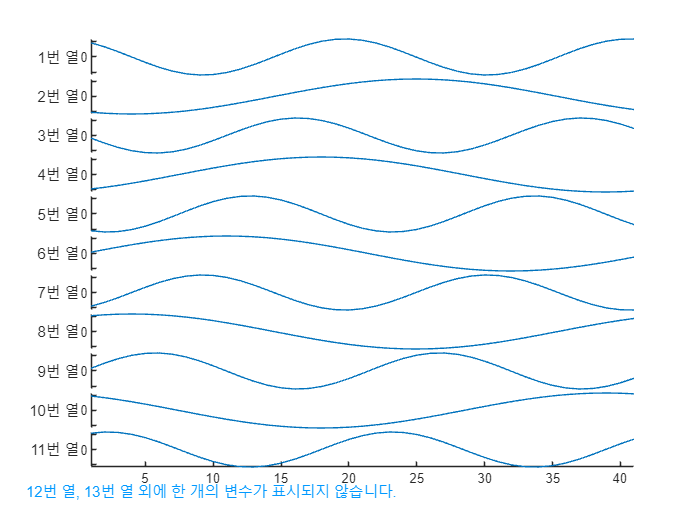

stackedplot(d_joint_data)

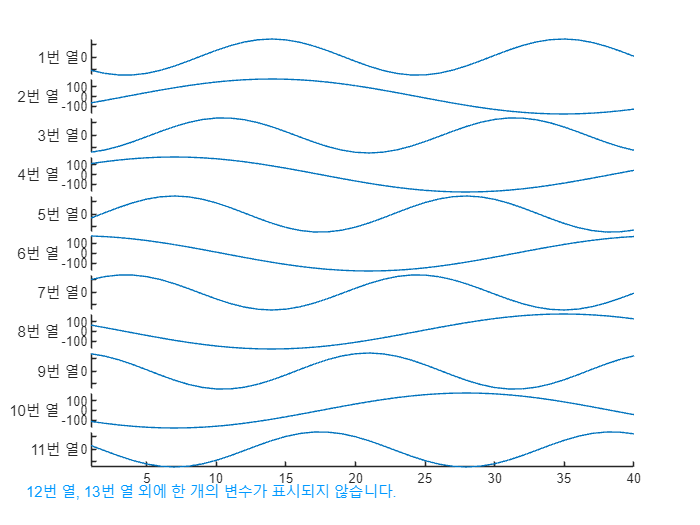

stackedplot(dd_joint_data)

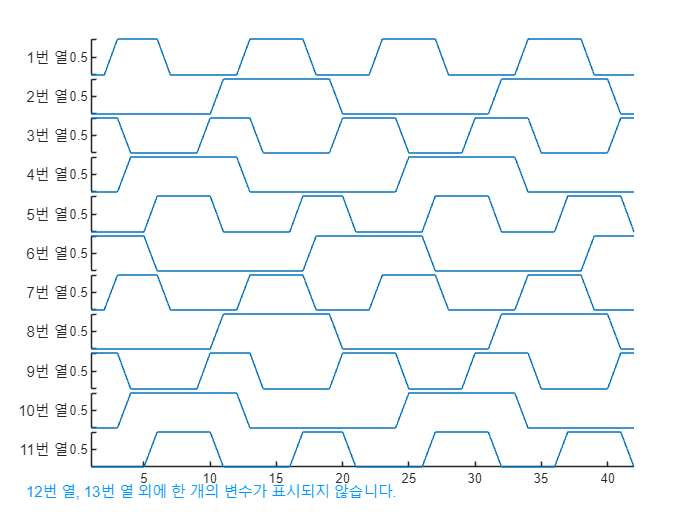

stackedplot(logic_joint)

아래는 속도 기반 Gait 모션 행렬의 구분을 위한 내용임.

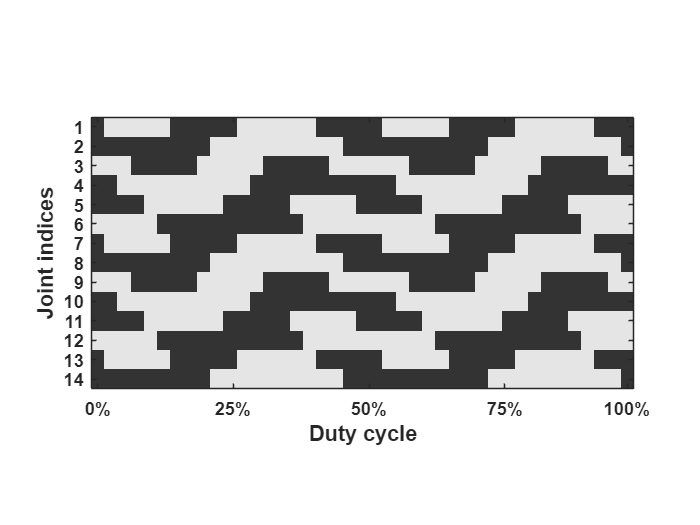

scale = 0.7071; %미분했을 때, 최대 값에서 어느정도 비율까지 움직이는 것으로 정의할지...
% scale = 0.9; %미분했을 때, 최대 값에서 어느정도 비율까지 움직이는 것으로 정의할지...

d_max = max(d_joint_data);
% d_max = mean(d_max);

d_M = abs(d_joint_data) > scale * d_max;

d_M = transpose(d_M);

figure; hAxes = gca;
imagesc(hAxes, d_M);
colormap( hAxes , [0.9 0.9 0.9; 0.2 0.2 0.2] )
pbaspect([2 1.2 1]);
yticks(1:1:14);
% yticklabels(["D1","L1","D2","L2","D3","L3","D4","L4","D5","L5","D6","L6","D7","L7"]);
a = get(gca,'YTickLabel');  
set(gca,'YTickLabel',a,'fontsize',11,'FontWeight','bold')
% % set(gca,'YTickLabelMode','auto')

xticks([1:length(d_M)/4:length(d_M), length(d_M)]);
xticklabels(["0%","25%","50%","75%","100%"]);
a = get(gca,'XTickLabel');  
set(gca,'XTickLabel',a,'fontsize',11,'FontWeight','bold')
% set(gca,'XTickLabelMode','auto')

xlabel("Duty cycle","FontSize",13,"FontName","arial","FontWeight","bold");
ylabel("Joint indices","FontSize",13,"FontName","arial","FontWeight","bold");

% axis off;
% grid on;

pbaspect([2 1 1])

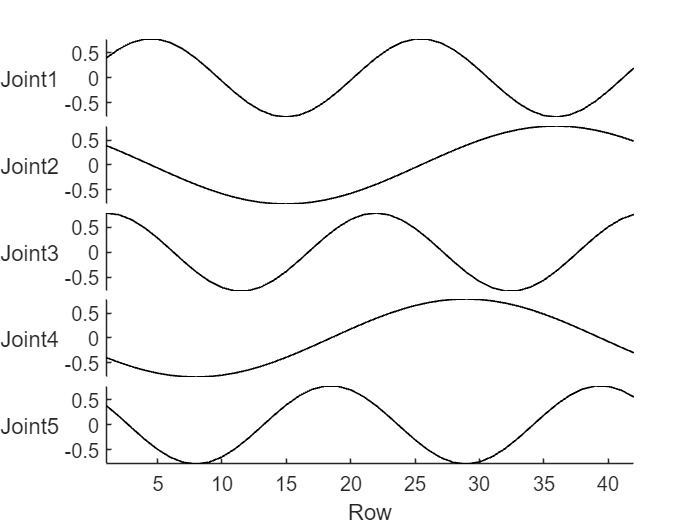

figure;

joint_pos = array2table(joint_data(:,1:5),"VariableNames",{'Joint1','Joint2','Joint3','Joint4','Joint5'});
fig = stackedplot(joint_pos,LineWidth=1.5,Color='k');
fig.FontSize = 12;
fig.FontName = 'arial';

% yticks = -pi/3:pi/6:pi/2;
% xticks([1:length(d_M)/4:length(d_M), length(d_M)]);
% axis off;
% grid on;
grid_ax = gca;
grid_ax.LineWidth = 1;

% grid_ax.GridLineStyle = "--";
% grid_ax.GridColor = [0.2 0.2 0.2];


% X = ax.XAxis;
% Y = ax.YAxis;
% X.FontSize = 11;
% Y.FontSize = 11;
% X.FontName = 'arial';
% Y.FontName = 'arial';
% X.FontWeight = 'bold';
% Y.FontWeight = 'bold';
% ax.Color = '#f3f4fe';